path = dir("G:\My Drive\1. Projects\PHYS-559 Graduate Laboratory (Spring 2023)\NMR Project\Final Paper Data\0.1224\*.csv")

path = 32×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


sampleConcentration = '0.1224M'

sampleConcentration = '0.1224'

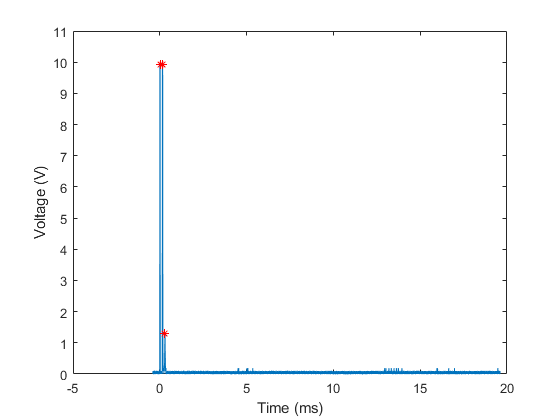

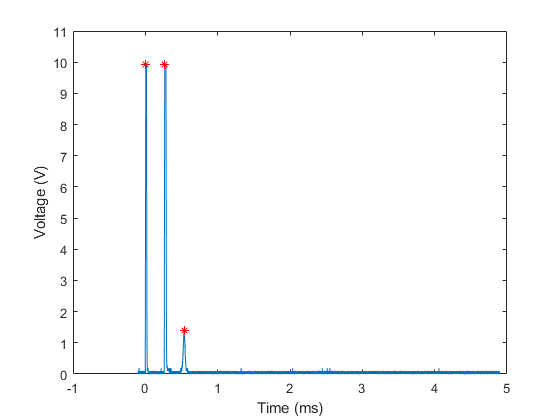

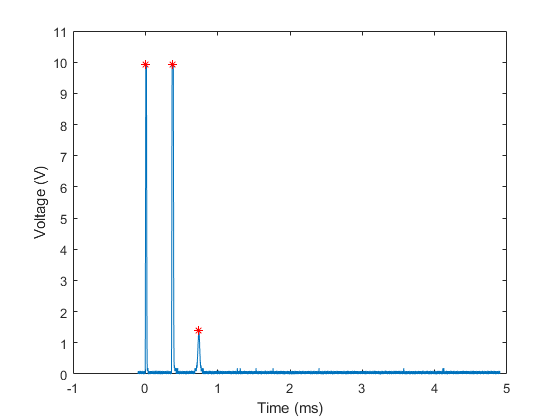

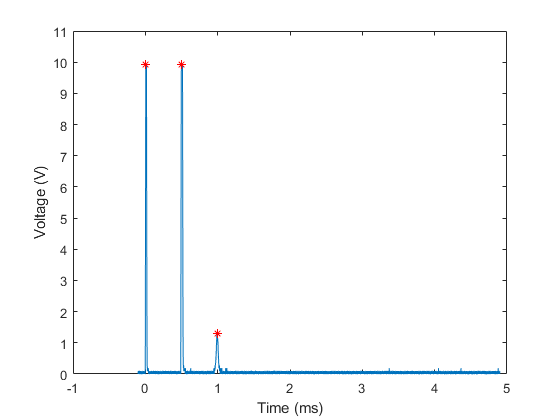

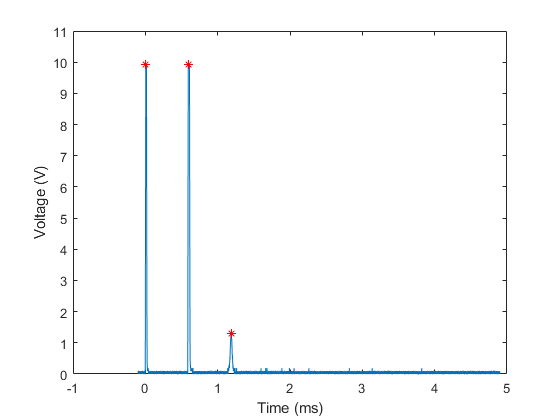

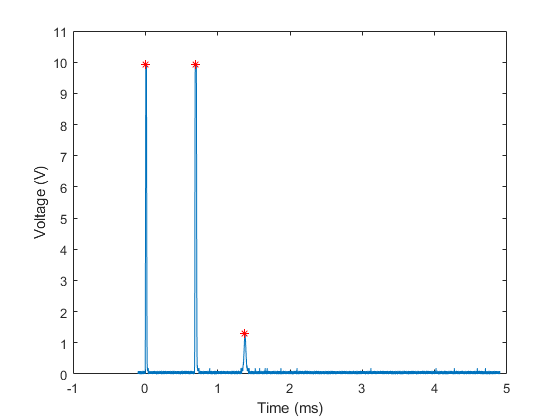

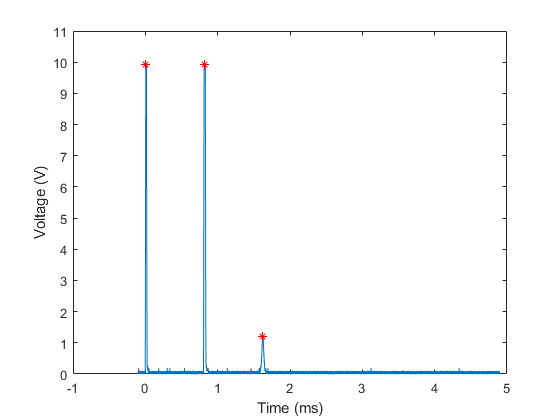

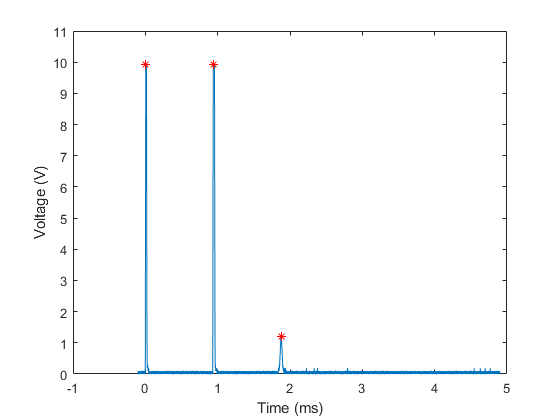

pulse_seperation =     0.1506    0.2623    0.3637    0.4909    0.5873    0.6828    0.8062    0.9328    1.0538    1.1774    1.3140    1.4317    1.5377    1.6513    1.8173    1.9533    2.0890    2.2967    2.5971    2.7959    3.0472    3.2580    3.4871    3.6590    3.9021    4.1271    4.3245    4.5378    4.7615    4.9826


spinEchoAmp =     1.3100    1.4035    1.4035    1.3100    1.3100    1.3100    1.2165    1.2165    1.2165    1.1230    1.1230    1.1230    1.1230    1.0292    1.0292    1.0292    0.9357    0.9357    0.8422    0.7486    0.7486    0.6548    0.6548    0.6548    0.5613    0.5613    0.5613    0.4678    0.4678    0.4678


[pulse_seperation, spinEchoAmp] = NMRdataAnalysis(path,sampleConcentration)

logSpinEchoAmp = log(spinEchoAmp)

logSpinEchoAmp =     0.2700    0.3390    0.3390    0.2700    0.2700    0.2700    0.1960    0.1960    0.1960    0.1160    0.1160    0.1160    0.1160    0.0287    0.0287    0.0287   -0.0665   -0.0665   -0.1718   -0.2895   -0.2895   -0.4234   -0.4234   -0.4234   -0.5774   -0.5774   -0.5774   -0.7597   -0.7597   -0.7597


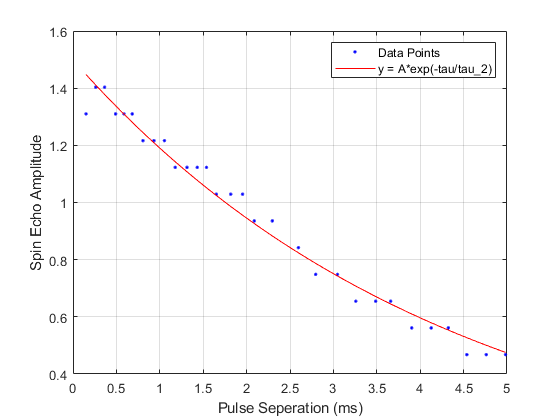

fitresult =      General model:
     fitresult(t) = A*exp(-t/t_2)
     Coefficients (with 95% confidence bounds):
       A =       1.499  (1.46, 1.537)
       t_2 =       4.342  (4.071, 4.612)

gof = struct with fields:
           sse: 0.0541
       rsquare: 0.9806
           dfe: 28
    adjrsquare: 0.9799
          rmse: 0.0440


[fitresult, gof] = exponentialFit(pulse_seperation, spinEchoAmp)

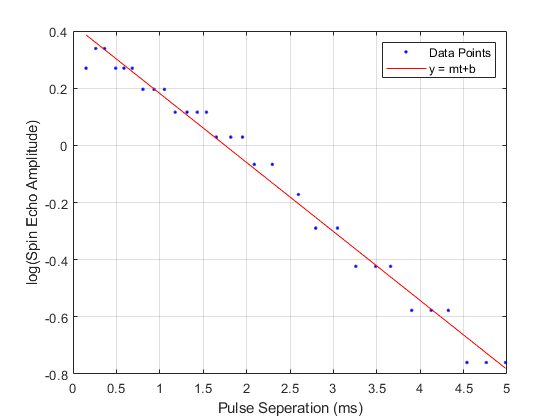

fitresult =      Linear model Poly1:
     fitresult(x) = p1*x + p2
       where x is normalized by mean 2.203 and std 1.491
     Coefficients (with 95% confidence bounds):
       p1 =     -0.3598  (-0.3771, -0.3424)
       p2 =      -0.109  (-0.126, -0.09191)

gof = struct with fields:
           sse: 0.0583
       rsquare: 0.9847
           dfe: 28
    adjrsquare: 0.9842
          rmse: 0.0456


[fitresult, gof] = linearFit(pulse_seperation, logSpinEchoAmp)

function [fitresult, gof] = exponentialFit(pulse_seperation, spinEchoAmp)
%CREATEFIT(PULSE_SEPERATION,SPINECHOAMP)
%  Create a fit.
%
%  Data for 'untitled fit 1' fit:
%      X Input : pulse_seperation
%      Y Output: spinEchoAmp
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 19-Feb-2023 22:36:59


%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( pulse_seperation, spinEchoAmp );

% Set up fittype and options.
ft = fittype( 'A*exp(-t/t_2)', 'independent', 't', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.0461713906311539 0.0971317812358475];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'Exponential Fit' );
h = plot( fitresult, xData, yData );
legend( h, 'Data Points', 'y = A*exp(-tau/tau_2)', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'Pulse Seperation (ms)', 'Interpreter', 'none' );
ylabel( 'Spin Echo Amplitude', 'Interpreter', 'none' );
grid on
end
function [fitresult, gof] = linearFit(pulse_seperation, logSpinEchoAmp)
%CREATEFIT1(PULSE_SEPERATION,LOGSPINECHOAMP)
%  Create a fit.
%
%  Data for 'Linear Fit' fit:
%      X Input : pulse_seperation
%      Y Output: logSpinEchoAmp
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 19-Feb-2023 22:39:47


%% Fit: 'Linear Fit'.
[xData, yData] = prepareCurveData( pulse_seperation, logSpinEchoAmp );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, 'Normalize', 'on' );

% Plot fit with data.
figure( 'Name', 'Linear Fit' );
h = plot( fitresult, xData, yData );
legend( h, 'Data Points', 'y = mt+b', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'Pulse Seperation (ms)', 'Interpreter', 'none' );
ylabel( 'log(Spin Echo Amplitude)', 'Interpreter', 'none' );
grid on
end

